# Auto-generated by Image Acquisition Explorer

Generated in MATLAB R2023b on 01-Oct-2024 08:45:06

## Connect to Device

Create connection to the device using the specified adaptor with the specified format.

v = videoinput("winvideo", 1, "YUY2_640x360");
%640x360 taka rozdzielczość bo używałęm kamery z laptopa

## Configure Device Properties

Configure videoinput properties to prepare for acquisition.

v.ReturnedColorspace = "rgb";

## Record Video for Set Number of Frames

Record video data for a specified number of frames.

numFrames = 10;
v.FramesPerTrigger = numFrames;

start(v);
wait(v);
stop(v);
recording1 = getdata(v, numFrames);

## Show Recording

View the recorded video.

implay(recording1);

## Clean Up

Delete the videoinput object and clear variables from the workspace.

delete(v)
clear v

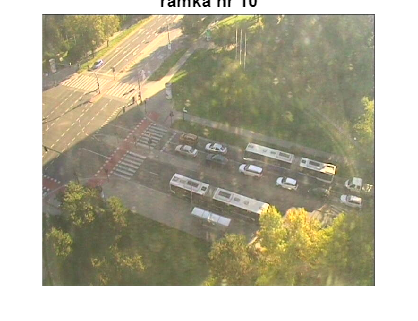

fh = figure;
ile_ramek = 10;
elapsedTime=zeros(1,ile_ramek);
for i = 1:ile_ramek
 tic
 IM = imread('http://149.156.124.49/axis-cgi/jpg/image.cgi');
 elapsedTime(1, i) = toc;

 imshow(IM);
 title(['ramka nr ' num2str(i)])
 drawnow
end

disp(['FPS = ' num2str(1/mean(elapsedTime))])

FPS = 1.2921


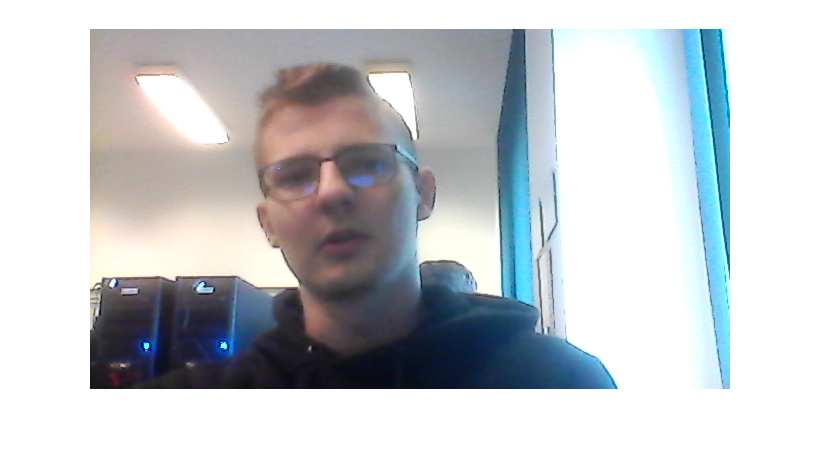

imageViewer(snapshot3)
imshow(snapshot3)



%% Inicjalizacja
camera       = webcam(1);           % ustawic odpowiedni nr kamery

% preview(cam); % podgląd obrazu z kamery
camera.AvailableResolutions

ans = 1×2 cell array
    {'640x480'}    {'640x360'}



camera.Resolution = '640x480';      % ustawić rozdzielczosć obsługiwaną przez kamerę

%% Akwizycja obrazów
figure

keepRolling = true;
iter =1;
ile_ramek = 100;
set(gcf,'CloseRequestFcn','keepRolling = false; closereq');
elapsedTime=zeros(1,ile_ramek);

while keepRolling & iter<ile_ramek
    tic;
    im = snapshot(camera);
    elapsedTime(1, iter) = toc;
    if ~isempty(im)        
        image(im)              
        title(['ramka ' num2str(iter)]);
        xlabel('aby zakończyć przykład zamknij okno lub poczekaj')
        drawnow
    end
    iter=iter+1;    
end

Timeout occurred while trying to get a frame from the webcam.

disp(['FPS = ' num2str(1/mean(elapsedTime))])
% Usuniecie obiektu kamery 
% (wymagane bo innaczej MATLAB nie zwolni zasobow sprzetowych)
clear camera

close all